close all; clear; clc;
Resultspath = "results\";
% fclose all;

subpaths = dir();
subpaths = subpaths(3:end);


for i = 1:length(subpaths)
    if(subpaths(i).name(1) == "_")
        
    end
end

subpaths

subpaths = 10×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


subpaths = subpaths(1:2)

subpaths = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



for i = 1:length(subpaths)
    subsubpaths = dir(subpaths(i).name);
    subsubpaths = subsubpaths(3:end);
    for j = 1:length(subsubpaths)
        subsubpaths(j)
    end
%     if(i == 1 && strcmp(NoBatchNormFC_selection(i),"all"))
%         files.NoBatchNormFC = [files.NoBatchNormFC, NoBatchNormFC];
%         break;
%     end
%     for j = 1:length(NoBatchNormFC)
%         if(strcmp(NoBatchNormFC(j).name,NoBatchNormFC_selection(i)))
%             files.NoBatchNormFC = [files.NoBatchNormFC, NoBatchNormFC(j)];
%         end
%     end
end

ans = struct with fields:
       name: 'N1_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DQN'
       date: '21-Dec-2021 13:58:31'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N2_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DQN'
       date: '21-Dec-2021 13:58:49'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N4_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DQN'
       date: '21-Dec-2021 14:30:19'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N6_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DQN'
       date: '21-Dec-2021 14:32:19'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'Old'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DQN'
       date: '20-Dec-2021 23:32:51'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N1_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DuelingDQN'
       date: '21-Dec-2021 14:33:38'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N2_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DuelingDQN'
       date: '21-Dec-2021 14:34:14'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N4_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DuelingDQN'
       date: '21-Dec-2021 14:34:52'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05


ans = struct with fields:
       name: 'N6_Layers'
     folder: 'D:\APA\APA_Assignment_3\DeepRL_PartIandII\results\DuelingDQN'
       date: '21-Dec-2021 14:35:15'
      bytes: 0
      isdir: 1
    datenum: 7.3851e+05




for i = 1:length(NoBatchNormFC_selection)
    if(i == 1 && strcmp(NoBatchNormFC_selection(i),"all"))
        files.NoBatchNormFC = [files.NoBatchNormFC, NoBatchNormFC];
        break;
    end
    for j = 1:length(NoBatchNormFC)
        if(strcmp(NoBatchNormFC(j).name,NoBatchNormFC_selection(i)))
            files.NoBatchNormFC = [files.NoBatchNormFC, NoBatchNormFC(j)];
        end
    end
end

Unrecognized function or variable 'NoBatchNormFC_selection'.

for i = 1:length(base_selection)
    if(i == 1 && strcmp(base_selection(i),"all"))
        files.base = [files.base, base];
        break;
    end
    for j = 1:length(base)
        if(strcmp(base(j).name,base_selection(i)))
            files.base = [files.base, base(j)];
        end
    end
end
for i = 1:length(Aug_selection)
    if(i == 1 && strcmp(Aug_selection(i),"all"))
        files.Aug = [files.Aug, Aug];
        break;
    end
    for j = 1:length(Aug)
        if(strcmp(Aug(j).name,Aug_selection(i)))
            files.Aug = [files.Aug, Aug(j)];
        end
    end
end
for i = 1:length(NoAug_selection)
    if(i == 1 && strcmp(NoAug_selection(i),"all"))
        files.NoAug = [files.NoAug, NoAug];
        break;
    end
    for j = 1:length(NoAug)
        if(strcmp(NoAug(j).name,NoAug_selection(i)))
            files.NoAug = [files.NoAug, NoAug(j)];
        end
    end
end
for i = 1:length(AugHalf_selection)
    if(i == 1 && strcmp(AugHalf_selection(i),"all"))
        files.AugHalf = [files.AugHalf, AugHalf];
        break;
    end
    for j = 1:length(AugHalf)
        if(strcmp(AugHalf(j).name,AugHalf_selection(i)))
            files.AugHalf = [files.AugHalf, AugHalf(j)];
        end
    end
end

files

f_data = [];

fields = fieldnames(files);

for p = 1:length(fields)
    if isempty(files.(fields{p}))
        continue;
    end
    
    [~, reindex] = sort( str2double( regexp( {files.(fields{p}).name}, '\d+', 'match', 'once' )));
    subpaths = files.(fields{p});
    subpaths = subpaths(reindex);
    
%     subpaths = files.(fields{p});
    
    nFiles = length(files.(fields{p}));
    
    for i = 1:nFiles
        fname = Resultspath+subpaths(i).path+subpaths(i).name+"\data.json";
        json = fileread(fname);
        temp = jsondecode(json);
        temp.Name = [char(subpaths(i).path),char(temp.Name)];
        f_data = [f_data temp];
    end
end

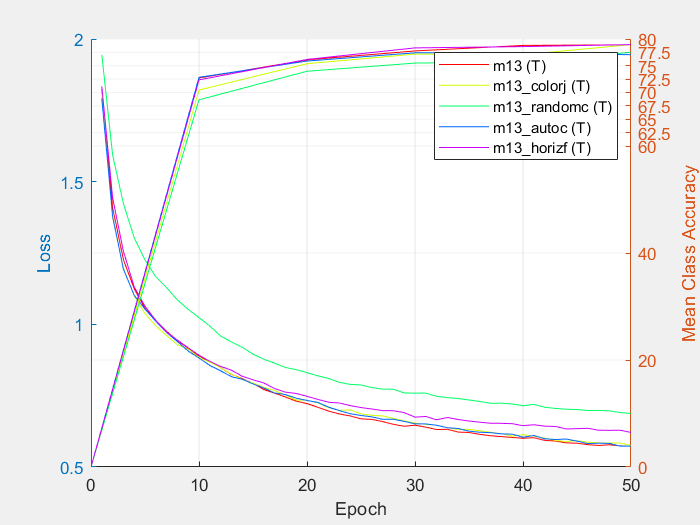

close all
f = figure;
set(f,'Visible','on');
hold on

c = hsv(length(f_data));


for i = 1:length(f_data)
    yyaxis right
    tick_size = f_data(i).NumberOfEpochs/f_data(i).NumberOfSteps;
    plot(0:tick_size:f_data(i).NumberOfEpochs,[0;f_data(i).MeanClassAccuracy],'Color',c(i,:),'Marker', 'none','LineStyle','-','Tag',strcat(f_data(i).Name,'_r'));
%     if strcmp(f_data(i).Name(end-1:end),'et')
%         plot([0:tick_size:150],[0;f_data(i).MeanClassAccuracy]','Color',c(i,:),'Marker', 'none','LineStyle','-','Tag',strcat(f_data(i).Name,'_r'));
%     else
%         
%     end
    yyaxis left
    plot(f_data(i).Loss_Epoch(:,1),f_data(i).Loss_Epoch(:,2),'Color',c(i,:),'Marker', 'none','LineStyle','-','Tag',strcat(f_data(i).Name,'_l'));
end







interactiveLegend(f,{f_data(:).Name});

yyaxis left
ylabel('Loss')

yyaxis right
xlabel('Epoch')
ylabel('Mean Class Accuracy')
xlim('auto')
ylim('auto')
ax = gca;
ticks = [0:20:60,(60+5/2):5/2:ax.YTick(end)];
ax.YTick = ticks;
ax.XTick = 0:10:ax.XTick(end);
yyaxis right

% Grids

xlims = [0,ax.XTick(end)];
ylims = [0,ax.YTick(end)];
for i = xlims(1):10:xlims(2)
    for j = ticks
        patch(xlims,[1,1]*j,'k','Marker', 'none','LineStyle','-','edgealpha',0.005);
        patch([1,1]*i,ylims,'k','Marker', 'none','LineStyle','-','edgealpha',0.005);
    end
end